% SIMULERING AF SYSTEM
% 7 mikrofoner får et input a 1, 3, 10 kHz
% deres input er justeret efter position i array
% 3 ULAer med 3 mikrofoninput i hver 
% DAS på hver ULA - kræver fractional delay
% Frekvensfiltrering før eller efter DAS??
% Sum outputs
% PSD

clc
clear
close all
% Change DAS parameters in DAS.mlx
load('DASParams.mat')

fs = 48e3;

%inputAng = 100 
steerAng % Main lobe steering direction from DAS.mlx

steerAng = 35.0100

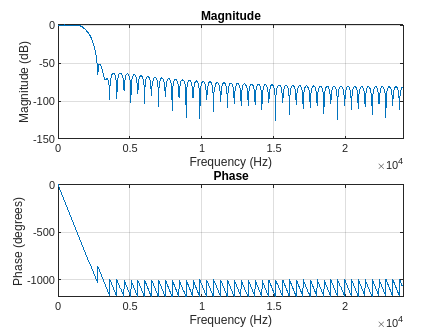

c = 1496;
%micTimeOffsets = micArray.*cosd(inputAng)/c
 % inputSig = sin(2*pi*(t+micTimeOffsets')*1000) ...
 %     + sin(2*pi*(t+micTimeOffsets')*3000) ...
 %     + sin(2*pi*(t+micTimeOffsets')*10000);
%inputSig = sin(2*pi*(t+micTimeOffsets').*linspace(1,24e3,length(t)))
%inputSig = sin(2*pi*(t+micTimeOffsets').*randi(24e3,1,length(t)))
zeroPad = 100;
%inputSig = [zeros(7,zeroPad) inputSig zeros(7,zeroPad)];


% Time offset in samples
tauOffset1 = tauULA1*fs; % Mic 1, 4, 7
tauOffset2 = tauULA2*fs; % Mic 2, 4, 6
tauOffset3 = tauULA3*fs; % Mic 3, 4, 5

% Fractional delays TBI

cfULA1 = 1700;
cfULA2 = [cfULA1 4500];
cfULA3 = cfULA2(2);

FIRULA1 = makeFIR(cfULA1, 100, fs, 'low');
FIRULA2 = makeFIR(cfULA2, 100, fs, 'bandpass');
FIRULA3 = makeFIR(cfULA3, 100, fs, 'high');
% freqz(FIRULA1,1,1024,fs);
% hold on

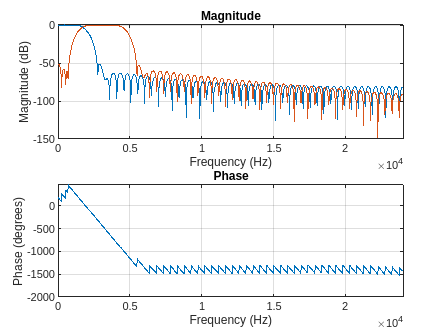

% freqz(FIRULA2,1,1024,fs);

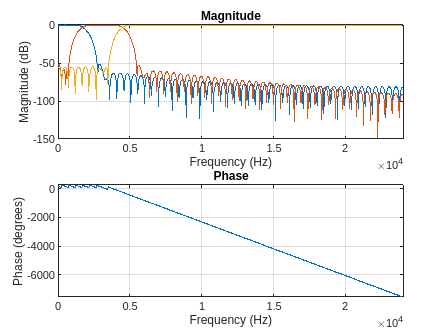

% freqz(FIRULA3,1,1024,fs);
% hold off


inputAng = linspace(0,180,181);
freqs = linspace(0, 24e3, 241);
freqs(1) = 20;
freqs(end) = 24e3-20;
t = 0:1/fs:0.1;
magRatio = zeros(length(inputAng),length(freqs));

f = waitbar(0,'Starting...','Name','Simulating DAS',...
    'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');

for ang = 1:length(inputAng)
    micTimeOffsets = micArray.*cosd(inputAng(ang))/c;
    for freq = 1:length(freqs)
        inputSig = sin(2*pi*(t+micTimeOffsets')*freqs(freq));

        % Filter inputs 
        inputSigULA1 = filter(FIRULA1,1,inputSig,[],2);
        inputSigULA1 = [zeros(7,zeroPad) inputSigULA1 zeros(7,zeroPad)];
        inputSigULA2 = filter(FIRULA2,1,inputSig,[],2);
        inputSigULA2 = [zeros(7,zeroPad) inputSigULA2 zeros(7,zeroPad)];
        inputSigULA3 = filter(FIRULA3,1,inputSig,[],2);
        inputSigULA3 = [zeros(7,zeroPad) inputSigULA3 zeros(7,zeroPad)];
        
        % Output of each ULA
        ULA1Sum = inputSigULA1(1,zeroPad+round(tauOffset1(1)):end-1-zeroPad-round(tauOffset1(spacing1)))...
            + inputSigULA1(4,zeroPad+round(tauOffset1(2)):end-1-zeroPad+round(tauOffset1(2))) ...
            + inputSigULA1(7,zeroPad+round(tauOffset1(3)):end-1-zeroPad+round(tauOffset1(3)));
        ULA1Sum = ULA1Sum * 1/3;
        
        ULA2Sum = inputSigULA2(2,zeroPad+round(tauOffset2(1)):end-1-zeroPad-round(tauOffset2(1)))...
            + inputSigULA2(4,zeroPad+round(tauOffset2(2)):end-1-zeroPad+round(tauOffset2(2))) ...
            + inputSigULA2(6,zeroPad+round(tauOffset2(3)):end-1-zeroPad+round(tauOffset2(3)));
        ULA2Sum = ULA2Sum * 1/3;
        
        ULA3Sum = inputSigULA3(3,zeroPad+round(tauOffset3(1)):end-1-zeroPad-round(tauOffset3(1)))...
            + inputSigULA3(4,zeroPad+round(tauOffset3(2)):end-1-zeroPad+round(tauOffset3(2))) ...
            + inputSigULA3(5,zeroPad+round(tauOffset3(3)):end-1-zeroPad+round(tauOffset3(3)));
        ULA3Sum = ULA3Sum * 1/3;
        
        arrayOutput = (ULA1Sum + ULA2Sum + ULA3Sum);
        %magRatio(ang,freq) = mean(arrayOutput.^2)/mean(sum(inputSig.^2,1))';
        magRatio(ang,freq) = mean(arrayOutput.^2)/mean(mean(inputSig.^2,2))';

    end
    setappdata(f,'canceling',0);
    waitbar(ang/length(inputAng),f,sprintf('%d°',inputAng(ang)))
end
delete(f)


## Plot BPs and DF

magRatiodB = 10*log10(magRatio)

magRatiodB =    -0.0377   -0.0411   -0.0501   -0.0631   -0.0856   -0.1271   -0.1892   -0.2559   -0.3026   -0.3192   -0.3282   -0.3812   -0.5420   -0.8708   -1.4138   -2.1874   -3.1379   -4.0639   -4.5811   -4.3752   -3.5826   -2.6092   -1.7419   -1.0869   -0.6488   -0.3905   -0.2618   -0.2132   -0.2041   -0.2077   -0.2120   -0.2167   -0.2263   -0.2423   -0.2589   -0.2625   -0.2378   -0.1746   -0.0740    0.0514    0.1811    0.2930    0.3678    0.3933    0.3664    0.2944    0.1938    0.0859   -0.0098   -0.0823
   -0.0377   -0.0411   -0.0501   -0.0630   -0.0855   -0.1269   -0.1889   -0.2555   -0.3022   -0.3186   -0.3274   -0.3803   -0.5409   -0.8695   -1.4124   -2.1859   -3.1365   -4.0629   -4.5809   -4.3757   -3.5835   -2.6100   -1.7425   -1.0872   -0.6489   -0.3905   -0.2617   -0.2130   -0.2039   -0.2074   -0.2117   -0.2164   -0.2260   -0.2420   -0.2585   -0.2621   -0.2374   -0.1742   -0.0735    0.0518    0.1816    0.2935    0.3683    0.3937    0.3668    0.2947    0.1941    0.0862   -0.

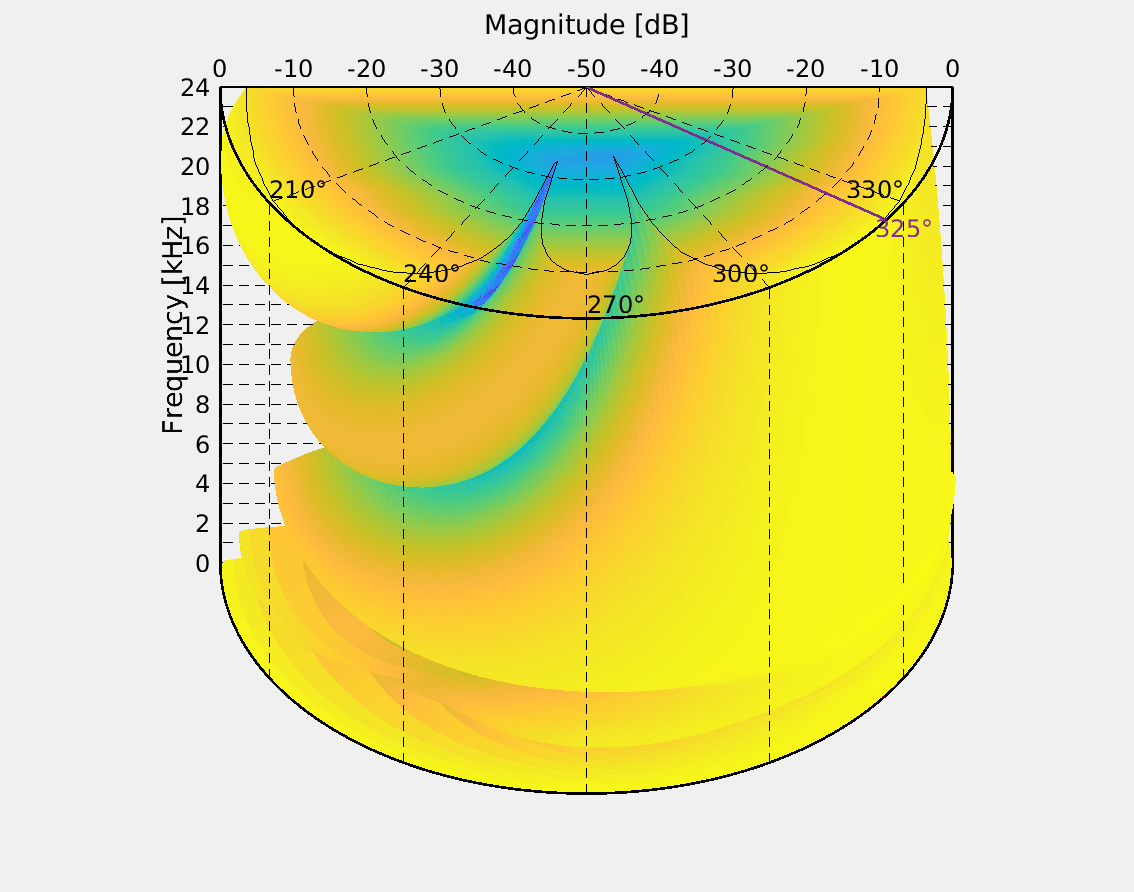

indexHz = find(freqs==23e3); % Find design frequency in sweep list
plotVisibility = 'on';

% figure(1)
% set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
%           'OuterPosition', [0 0 30 20]) %21/2-2*2
% circPlot(freqs(indexHz), inputAng*pi/180, magRatiodB(:,indexHz)', steerAng)

figure(2)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 30])
cylindricalPlot(freqs, inputAng*pi/180, magRatiodB', steerAng)


% figure(3)
% plot(micArray, zeros(length(micArray),1), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'g')
% hold on
% %text(micArray, zeros(length(micArray),1)+0.5+(-1).^(0:length(micArray)-1)'*0.12, string(round(micArray,3)), 'HorizontalAlignment', 'center', 'FontSize', 12)
% text(micArray, zeros(length(micArray),1)+0.5+[0 0 0.12 -0.12 0.12 0 0]', string(round(micArray,3)), 'HorizontalAlignment', 'center', 'FontSize', 12)
% text(micArray, zeros(length(micArray),1)-0.5, 'Q' + string(0:length(micArray)-1), 'HorizontalAlignment', 'center', 'FontSize', 12)
% pbaspect([8 1 1])
% set(gca,'YTickLabel',{' '})
% xlim([-0.05 1.05])
% grid minor
% hold off

## Generate .c and .h files

% Check for "length should be divided by 4 and aligned to 16"
% for f = ["FIRULA1" "FIRULA2" "FIRULA3"]
%     if mod(length(eval('f')),16) ~= 0
%         %padLength = bitand(int(length(FIRULA1) + 3), bitcmp(3))
%         %padLength = 4 * ceil((length(FIRULA1) + 3) / 4);
%         padLength = 16-mod(length(eval('f')),16)
%         eval('f') = zeros(length(eval('f'))+padLength,1)'
%         %mod(length(eval('f'))+padLength,16)
%     end
% end

% if mod(length(FIRULA1),16) ~= 0
%     padLength = 16-mod(length(FIRULA1),16)
%     FIRULA1 = [FIRULA1 zeros(1,padLength)]
% end
% 
% if mod(length(FIRULA2),16) ~= 0
%     padLength = 16-mod(length(FIRULA2),16)
%     FIRULA2 = [FIRULA2 zeros(1,padLength)]
% end
% 
% if mod(length(FIRULA3),16) ~= 0
%     padLength = 16-mod(length(FIRULA3),16)
%     FIRULA3 = [FIRULA3 zeros(1,padLength)]
% end

% Get the dimensions of the matrix
FIR1Length = length(FIRULA1);
FIR2Length = length(FIRULA2);
FIR3Length = length(FIRULA3);

% Open the header file for writing
fid_h = fopen('DAS/main/FIRWeights.h', 'w');

% Write the header file contents
%fprintf(fid_h, '#include <complex.h>\n\n');
fprintf(fid_h, '#ifndef FIRWEIGHTS_H\n');
fprintf(fid_h, '#define FIRWEIGHTS\n\n');

fprintf(fid_h, '#define FIR1LENGTH %d\n', FIR1Length);
fprintf(fid_h, '#define FIR2LENGTH %d\n', FIR2Length);
fprintf(fid_h, '#define FIR3LENGTH %d\n\n', FIR3Length);
fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR1WEIGHTS[FIR1LENGTH] = \n\t{');
for r = 1:FIR1Length
    fprintf(fid_h, '%f', cast(FIRULA1(r),"single"));
    if r < FIR1Length
        fprintf(fid_h, ',');
    end
end
fprintf(fid_h, '};\n\n');

fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR2WEIGHTS[FIR2LENGTH] = \n\t{');
for r = 1:FIR2Length
    fprintf(fid_h, '%f', cast(FIRULA2(r),"single"));
    if r < FIR2Length
        fprintf(fid_h, ',');
    end
end
fprintf(fid_h, '};\n\n');


fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR3WEIGHTS[FIR3LENGTH] = \n\t{');
for r = 1:FIR3Length
    fprintf(fid_h, '%f', cast(FIRULA3(r),"single"));
    if r < FIR3Length
        fprintf(fid_h, ',');
    end
end
fprintf(fid_h, '};\n\n');

fprintf(fid_h, '#endif // FIRWEIGHTS_H\n');

% Close the header file
fclose(fid_h);

disp('Header file generated successfully.');

Header file generated successfully.


function coeffs_adjusted = makeFIR(Fc, order, fs, type)
if ~exist('type', 'var') 
    coeffs = fir1(order,2*Fc/fs);
else 
    coeffs = fir1(order,2*Fc/fs, type);
end 
[mag, freq] = freqz(coeffs,1,1024,fs);
magdB = 20*log10(abs(mag));
if length(Fc) == 1
    [~, minIndex] = min(abs(magdB + 3));
    Fc_3dB = freq(minIndex);
    Fc_adjusted = Fc * (Fc/Fc_3dB);
    coeffs_adjusted = fir1(order, 2*Fc_adjusted/fs, type);
elseif length(Fc) == 2
    %[~, minIndexLow] = min(abs(magdB + 3));
    minIndexLow = find(abs(magdB)<3,1);
    minIndexHigh = find(abs(magdB(minIndexLow:end))>3,1) + minIndexLow;
    FcLow_3dB = freq(minIndexLow);
    FcHigh_3dB = freq(minIndexHigh);
    FcLow_adjusted = Fc(1) * (Fc(1)/FcLow_3dB);
    FcHigh_adjusted = Fc(2) * (Fc(2)/FcHigh_3dB);
    coeffs_adjusted = fir1(order, 2*[FcLow_adjusted FcHigh_adjusted]/fs, type);
else
    disp("nederen")
end
end